# 作业

姓名：***

学号：***

## I. 清空环境变量

clear
clc


设定随机数种子

rng(0);%可以根据自己的需要设置seed值

## II. 建模

1. 导入建模数据

datatrain_=importdata('data.csv');
datatrain=datatrain_.data;
datatest_=importdata('testdata.csv');
datatest=datatest_.data;

2. 确定训练集、验证集

% 使用 80% 作为训练集，20% 作为验证集
trainSize = floor(0.8 * size(datatrain, 1));

3.划分输入数据和输出数据

% 特征选择（取C、Si、Mn、P、S、Cr、Ni、Mo、N、Strain是相关特征）
selected_features = [1, 2, 3, 4, 5, 6, 7, 8, 9,10,11,13,14,15,16,17]; 
X_train = datatrain(1:trainSize, selected_features);
y_train = datatrain(1:trainSize, end);
X_val = datatrain(trainSize+1:end, selected_features);
y_val = datatrain(trainSize+1:end, end);

4.数据归一化

% 计算均值和标准差用于归一化
[X_train_norm, mu_X, sigma_X] = zscore(X_train);
y_train_mean = mean(y_train);
y_train_std = std(y_train);
y_train_norm = (y_train - y_train_mean) / y_train_std;

% 使用相同的均值和标准差对验证集归一化
X_val_norm = (X_val - mu_X) ./ sigma_X;
y_val_norm = (y_val - y_train_mean) / y_train_std;

5. 创建网络

hiddenLayerSize = [30,40,20]; % 增加隐藏层并调整神经元数量
net = feedforwardnet(hiddenLayerSize);

6. 训练网络

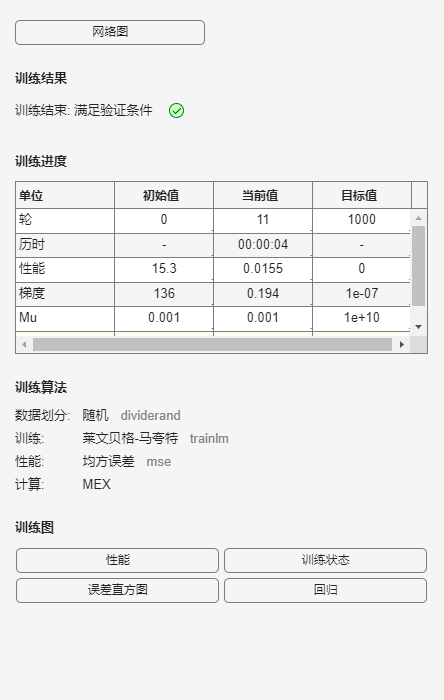

net = train(net, X_train_norm', y_train_norm');

7. 在验证集上测试

y_val_pred_norm = net(X_val_norm');

8.性能评价

y_val_pred = y_val_pred_norm' * y_train_std + y_train_mean; % 反归一化预测值
[MSE_val, R2_val] = evolution(y_val, y_val_pred); % 使用evolution函数计算MSE和R²
disp(['Validation MSE: ', num2str(MSE_val), ', R²: ', num2str(R2_val)]);

Validation MSE: 6.6417, R²: 0.56578


9.保存模型

save('model.mat', 'net');

## III. 导入测试数据预测

1. 导入数据

datatest_=importdata('testdata.csv');
datatest=datatest_.data;

2.划分输入数据和输出数据

% 1. 导入数据
datatest_X = datatest(:, selected_features); % 测试数据输入
datatest_y = datatest(:, end);     % 测试数据输出

3.利用基于训练数据建立的规则进行数据归一化

datatest_X_norm = (datatest_X - mu_X) ./ sigma_X;

4.利用训练好模型预测

y_test_pred_norm = net(datatest_X_norm');

5. 预测结果反归一化

y_test_pred = y_test_pred_norm' * y_train_std + y_train_mean;

6. 测试数据上进行预测性能评价

[MSE_test, R2_test] = evolution(datatest_y, y_test_pred); % 使用evolution函数计算MSE和R²
disp(['Test MSE: ', num2str(MSE_test), ', R²: ', num2str(R2_test)]);

Test MSE: 8.9025, R²: 0.5105


7. 基于测试数据预测结果绘图并输出预测结果(均方误差MSE和决定系数R^2)

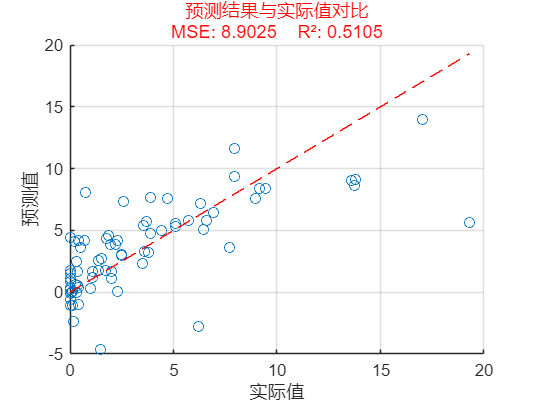

% 绘制散点图并标记对角线
figure;
scatter(datatest_y, y_test_pred);
hold on;
plot([min(datatest_y), max(datatest_y)], [min(datatest_y), max(datatest_y)], 'r--');
xlabel('实际值');
ylabel('预测值');
title('预测结果与实际值对比');
grid on;

% 使用 title 在标题正下方添加 MSE 和 R² 信息
title({
    '预测结果与实际值对比';
    ['MSE: ', num2str(MSE_test), '    R²: ', num2str(R2_test)]
    }, 'Color', 'r');

## IV. 使用训练好的模型预测新数据

1. 导入待预测数据

predict_data_ = importdata('predict.csv');
predict_data = predict_data_.data;

2. 划分输入数据和输出数据

predict_X = predict_data(:, selected_features);  % 输入变量
predict_y = predict_data(:, end);      % 输出变量（TCL）

3. 利用训练数据的均值和标准差进行数据归一化

predict_X_norm = (predict_X - mu_X) ./ sigma_X;

4. 利用训练好的模型预测

y_predict_norm = net(predict_X_norm');

5. 预测结果反归一化

y_predict = y_predict_norm' * y_train_std + y_train_mean;

6. 预测性能评价

[MSE_pred, R2_pred] = evolution(predict_y, y_predict); % 使用evolution函数计算MSE和R²
disp(['PREDICT MSE: ', num2str(MSE_pred), ', R²: ', num2str(R2_pred)]);

PREDICT MSE: 4.9446, R²: 0.66526


6. 输出预测结果

disp('预测结果:');

预测结果:


disp(table(predict_y, y_predict, 'VariableNames', {'实际TCL', '预测TCL'}));

    实际TCL    预测TCL 
    _______    ________

       3.2       1.2629
      3.45       3.0036
      4.84       4.7938
      0.38     -0.31001
      2.88       5.0171
      7.47       9.4398
      2.03       1.7227
      14.8        10.92
      8.03       8.0656
      2.67       4.3694
     11.28       10.692
         0     -0.75903
       3.2       3.0794
      9.76       6.7758
      6.43       6.8318
      1.11       2.3068
      1.98       3.7079
      6.24       4.6049
      0.47       3.0507
         3       2.9193
      1.27       5.0897
      10.1       9.7534
      1.94       2.9815
      6.17     -0.77234



7. 绘制预测结果和实际结果的对比图

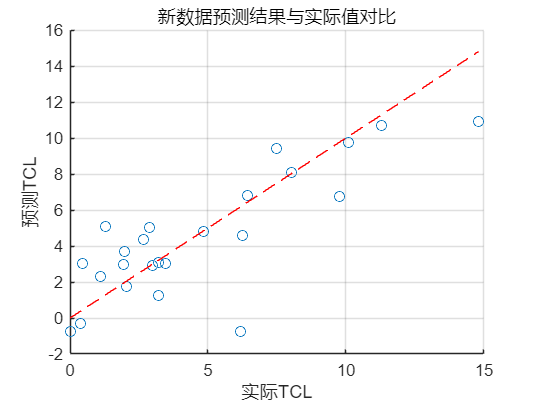

figure;
scatter(predict_y, y_predict);
hold on;
plot([min(predict_y), max(predict_y)], [min(predict_y), max(predict_y)], 'r--');
xlabel('实际TCL');
ylabel('预测TCL');
title('新数据预测结果与实际值对比');
grid on;